# Cviceni 11

## Orezavani oblasti

### UKOL 1 - Cohen-Sutherland

Upravte funkci `cs_kod`, ktera pro zadanou orezovou oblast a bod, vrati kod tohoto bodu definovany v Cohen-Sutherlandove metode pro orezavani usecek. 

Orezovy obdelnik je dan dvema body (levy horni roh a pravy dolni roh). 

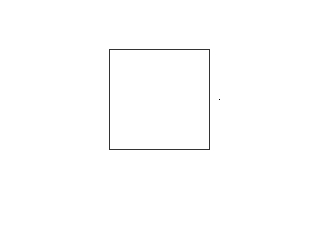

ans =      0     0     0     0


bod_oblasti1 = [0,0];
bod_oblasti2 = [100,100];
bod = [50,110];

cs_kod(bod_oblasti1,bod_oblasti2, bod)

## Interpolacni krivky

vq = interp1(v,xq,method)

### Spline

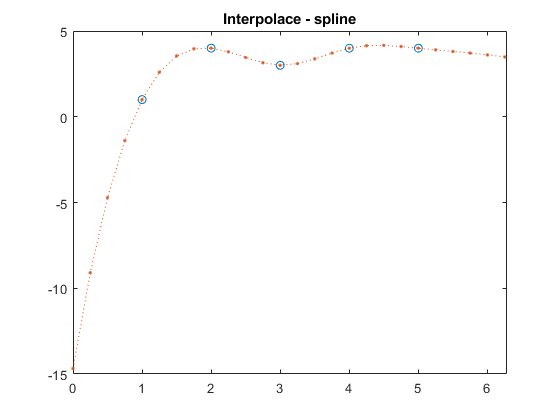

% kontrolni body
x= [1 2 3 4 5 7 8 10];
y = [1 4 3 4 4 3 2 1];

xx = 0:.25:10;
yy = interp1(x,y,xx,'spline');
plot(x,y,'o',xx,yy,':.');
xlim([0 2*pi]);
title('Interpolace - spline');

### Linearni interpolace

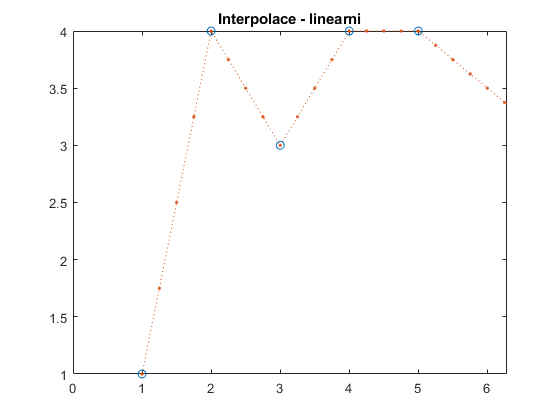

yy = interp1(x,y,xx,'linear');
plot(x,y,'o',xx,yy,':.');
xlim([0 2*pi]);
title('Interpolace - linearni');

### Kubicka interpolace 

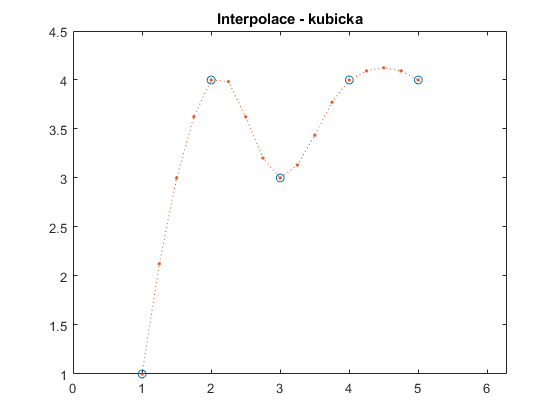

% potrebuje kontrolni body ve stejne vydalenosti, proto se berou jen prvni
yy = interp1(x(1:5),y(1:5),xx,'cubic');
plot(x,y,'o',xx,yy,':.');
xlim([0 2*pi]);
title('Interpolace - kubicka');

### Hermitovske kubiky

p(t)=(2t^3-3t^2+1)p_1+(t^3-2t^2+t)m_1+(-2t^3+3t^2)p_2+(t^3-t^2)m_2

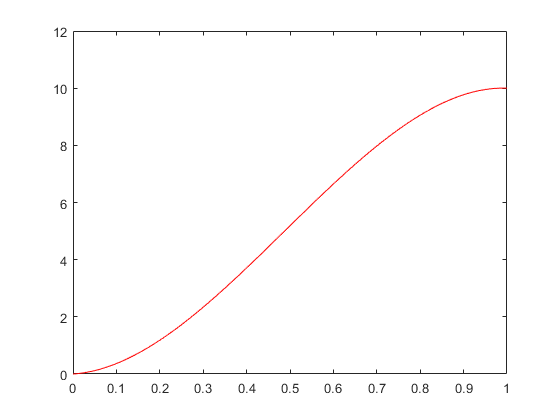

% body [x1,y1] a [x2,y2]
% tecny m1, m2
x1 = 0;
y1 = 0;
x2 = 1;
y2 = 10;

m1 = 1;
m2 = -0.5;

A = [x1^3,x2^3,3*x1^2,3*x2^2;x1^2,x2^2,2*x1,2*x2;x1,x2,1,1;1,1,0,0];
C = [y1,y2,m1,m2]/A; 

n = 1000;
X = linspace(x1,x2,n);
Y = C*[X.^3;X.^2;X;ones(1,n)];

figure, plot(X,Y,'r-')

## UKOL 2 - Aproximacni krivky 

Naprogramujte naivni algoritmus na vypocet aproximacni Bezierovy kubiky. 

B = bezier( t, P )

Funkce vrati bod pro zadane t a vektor 2 x n kontrolnich bodu. (v případě kubik je n = 4)

Vzorecek je na slidu 10 z prednasky 12.

Pro vypocet kombinacniho cisla pouzijte funkci nchoosek.

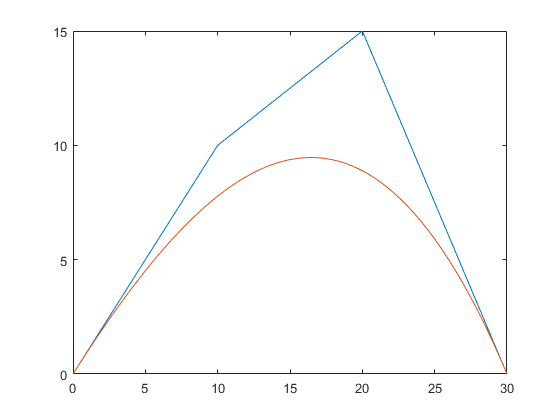

b = [];

P = [0 10 20 30;
     0 10 15 0];
for i = 0 : 0.01 : 1
    b = [b, bezier( i, P )];
end

figure, 
plot(P(1,:), P(2,:));
hold on;
plot(b(1,:), b(2,:));